# Practica 8. Aplicaciones del Procesamiento Digital de Señales

1. Utilice Matlacodlineapara generar señalescodlineainariasen codlineaanda codlineaase que utilicen

a) Pulsos rectangulares: $p\left(t\right)=\Pi \left(\frac{t}{T_b }\right)$

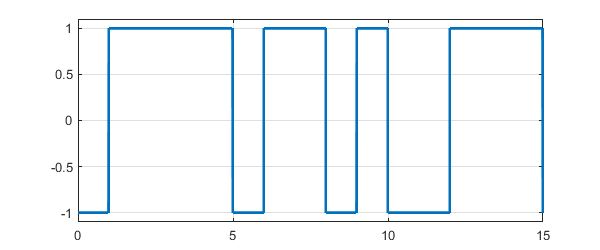

figure('Position',[500 400 600 250])
t = 0 :1e-6: 15; 
escalon = @(t) t>=0;
codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];
pulso = @(t) (escalon(t) - escalon(t- 1));
funcion1 = 0;
for i = 1 : 16
    funcion1 = funcion1 + codlinea(i) .* pulso(t - (i-1));
end
plot(t,funcion1,'Linewidth',2)
ylim ([-1.1 1.1])
grid on

codlinea) Pulsos sinc: $p\left(t\right)=\frac{\sin \left(\frac{\pi t}{T_b }\right)}{\frac{\pi t}{T_b }}$

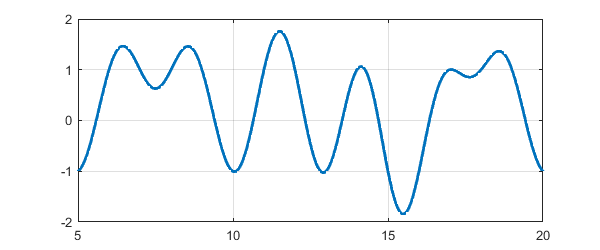

funcion2 = 0;
t = 0 :1e-6: 15; 
codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];
for i= 1 : 16
    funcion2 = funcion2 + codlinea(i) .* sinc(t - (i-1));
end
t1 = t+5; 
plot(t1,funcion2, 'Linewidth',2)
grid on

c) Coseno Alzado: $p\left(t\right)=\frac{\sin \left(\frac{\pi t}{T_b }\right)}{\frac{\pi t}{T_b }}\ldotp \frac{\cos \left(\frac{\alpha \pi t}{T_b }\right)}{1-{\left(\frac{2\alpha t}{T_b }\right)}^2 }$

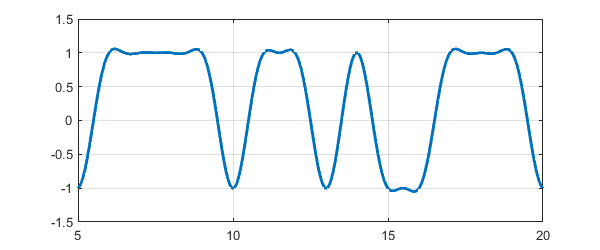

p3 = 0; 
codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];
t = 0 :1e-6: 15; 
ca = @(t) sinc(t) .* ( cos(pi*t) ./ (1-(2*t).^2 )) ;
for i=1 : 16
    p3 = p3 + codlinea(i) .* ca(t - (i-1)); 
end

plot(t1,p3, 'Linewidth',2)
grid on

2. Utilice Matlacodlineapara  simular  un  sistema  de  comunicaciones  digitales  codlineainario que  transmite en codlineaanda codlineaase a través de un canal con respuesta al impulso:

a) Represente gráficamente laseñala la entrada del canal de tiempo discreto.

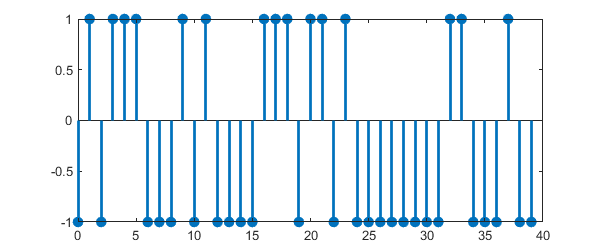

n = 0 : 1 : 39; 
escalon = @(n) n>=0;
codlinea = [-1 1 -1 1 1 1 -1 -1 -1 1 -1 1 -1 -1 -1 -1 1 1 1 -1 1 1 -1 1 -1 -1 -1 -1 -1 -1 -1 -1 1 1 -1 -1 -1 1 -1 -1];
pulso = @(n) (escalon(n) - escalon(n- 1));
x = 0;
for i=1 : 40
    x = x + codlinea(i) .* pulso(n - (i-1));
end
stem(n, x, 'filled', 'LineWidth',2); 

b) Represente gráficamente las señales a la salida del canal de tiempo discreto.

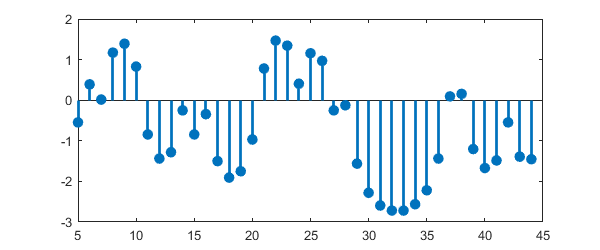

h = (0.5).^abs(-6:6);
y = conv(x,h,"same");
stem(n+5, y, "filled", 'LineWidth', 2); 

Anexo

figure('Position',[500 400 600 250])

t = 0 :1e-6: 15; 

escalon = @(t) t>=0;

codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];

pulso = @(t) (escalon(t) - escalon(t- 1));

funcion1 = 0;

for i = 1 : 16

    funcion1 = funcion1 + codlinea(i) .* pulso(t - (i-1));

end

plot(t,funcion1,'Linewidth',2)

ylim ([-1.1 1.1])

grid on

funcion2 = 0;

t = 0 :1e-6: 15; 

codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];

for i= 1 : 16

    funcion2 = funcion2 + codlinea(i) .* sinc(t - (i-1));

end

t1 = t+5; 

plot(t1,funcion2, 'Linewidth',2)

grid on

p3 = 0; 

codlinea = [-1 1 1 1 1 -1 1 1 -1 1 -1 -1 1 1 1 -1];

t = 0 :1e-6: 15; 

ca = @(t) sinc(t) .* ( cos(pi*t) ./ (1-(2*t).^2 )) ;

for i=1 : 16

    p3 = p3 + codlinea(i) .* ca(t - (i-1)); 

end

plot(t1,p3, 'Linewidth',2)

grid on

n = 0 : 1 : 39; 

escalon = @(n) n>=0;

codlinea = [-1 1 -1 1 1 1 -1 -1 -1 1 -1 1 -1 -1 -1 -1 1 1 1 -1 1 1 -1 1 -1 -1 -1 -1 -1 -1 -1 -1 1 1 -1 -1 -1 1 -1 -1];

pulso = @(n) (escalon(n) - escalon(n- 1));

x = 0;

for i=1 : 40

    x = x + codlinea(i) .* pulso(n - (i-1));

end

stem(n, x, 'filled', 'LineWidth',2);

h = (0.5).^abs(-6:6);

y = conv(x,h,"same");

stem(n+5, y, "filled", 'LineWidth', 2); 